This study starts from the operating duty and follows the hydraulic consequence of closing the downstream control valve.

The engineering question is practical: how slowly should the valve close to limit surge without making the actuator unnecessarily slow?

clear; close all; clc
g = 9.81; % m/s^2, gravitational acceleration

Representative water properties at 25°C are used for the steady-state and transient calculations.

% Fluid properties (water at ~20°C)
fluid.rho = 997.0;                  % kg/m^3, density
fluid.cp = 4180.0;                  % J/(kg*K), specific heat capacity
fluid.mu = 0.890e-3;                % Pa*s, dynamic viscosity
fluid.bulkModulus = 2.20e9;         % Pa, bulk modulus (compressibility)
fluid.vaporPressure = 3.17e3;       % Pa, vapor pressure (for cavitation checks)

The pipe model defines the length, diameter, wall thickness, roughness and elastic modulus needed for friction and wave-speed calculations.

% Pipe geometry and material properties
pipe.L = 100.0;                    % m, total pipe length

% Nominal size / schedule could be specified instead of explicit dimensions:
% pipe.nominalSize = "NPS 12 / DN 300";
% pipe.schedule = 40;

pipe.OD = 0.3238;                  % m, outside diameter
pipe.thickness = 0.00953;          % m, wall thickness
pipe.D = pipe.OD - 2*pipe.thickness; % m, internal (hydraulic) diameter
pipe.E = 200e9;                    % Pa, Young's modulus for steel
pipe.nu = 0.30;                    % Poisson's ratio (not used elsewhere here)
pipe.roughness = 4.5e-5;           % m, absolute roughness for commercial steel

% Derived hydraulic properties
pipe.area = pi * pipe.D^2 / 4;     % m^2, cross-sectional flow area
pipe.relativeRoughness = pipe.roughness / pipe.D; % dimensionless

The valve discharges to a receiving side with a fixed hydraulic head. The heat exchanger, fittings and fully open valve losses are combined to define the steady system resistance.

headAfterValve = 8.0;  % m, receiving-side hydraulic head

K_Exchanger = 40;   % equivalent K representing heat-exchanger pressure drop
K_fittings  = 10;   % combined loss from bends, tees, reducers and isolation fittings
K_valve     = 10;   % equivalent loss coefficient of the fully open control valve
K_total = K_fittings + K_Exchanger + K_valve;

The process duty sets the required cooling-water flow. For 4.2 MW of heat rejection and a 10°C water temperature rise, the heat balance gives the design flow.

Duty = 4.2e6; deltaT = 10;
Qdesign = Duty/(fluid.rho * fluid.cp * deltaT)

Qdesign = 0.1008

With the target flow established, the system curve is built from the static receiving head and the distributed and local hydraulic losses.

ReynoldsNumber = @(Q) fluid.rho .* ( Q ./ pipe.area ) .* pipe.D ./ fluid.mu;
frictionFactor = @(Q) 0.25 ./ log10(pipe.relativeRoughness ./ 3.7 + 5.74 ./ ReynoldsNumber(Q).^0.9).^2;
dynamicPressure = @(Q) ( Q ./ pipe.area ).^2 ./ ( 2.*g ); 

systemHead = @(Q) headAfterValve + ( frictionFactor(Q) * pipe.L / pipe.D + K_total ) .* dynamicPressure(Q);

A representative centrifugal pump is described by 23 m shutoff head and 17 m head at the design flow.

shutoffHead=23; designHead=17;
pumpHead = @(Q) shutoffHead - (shutoffHead-designHead) ./ Qdesign.^2 * Q.^2;

The actual operating point is where the pump curve and system curve intersect. This flow becomes the initial condition for the surge calculation.

residual = @(Q) pumpHead(Q)-systemHead(Q);
Q0 = fzero(residual,Qdesign)

Q0 = 0.1112

The pump and system curves provide a quick check that the selected operating point is hydraulically consistent.

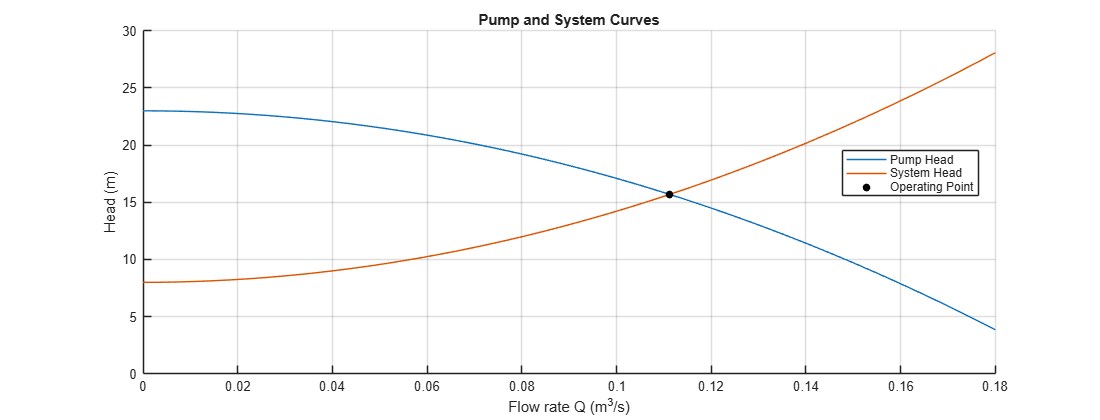

% Pump curve, system curve and resulting operating point
Qvec = linspace(0,0.18,50);
Hpump = pumpHead(Qvec);
Hsystem = systemHead(Qvec);

figure('Position',[140 140 1100 420]); hold on; grid on;
plot(Qvec,Hpump);
plot(Qvec,Hsystem);
plot(Q0,pumpHead(Q0),'ko','MarkerFaceColor','k','MarkerSize',5);
legend('Pump Head','System Head','Operating Point','Location','Best');
xlabel('Flow rate Q (m^3/s)');
ylabel('Head (m)');
title('Pump and System Curves');
xlim([0,max(Qvec)]);

At this operating point, the model now has the initial pipe heads, flow, friction level and pressure-wave travel time needed for transient analysis.

UpstreamHead0 = pumpHead(Q0); 
DownstreamHead0 = headAfterValve + K_valve * dynamicPressure(Q0);

waveSpeed = sqrt( ( fluid.bulkModulus /fluid.rho ) /( 1 + fluid.bulkModulus * pipe.D / ( pipe.E * pipe.thickness ) ) );
waveRoundTripTime = 2*pipe.L/waveSpeed;
systemDarcyFactor = frictionFactor(Q0) + K_total * pipe.D / pipe.L;


operatingPoint = table( ...
    ["Thermal design flow";"Operating flow";"Mean pipe velocity"; ...
    "Reynolds number";"Darcy friction factor"; "System total friction factor";"Pump/system head"; ...
    "Initial valve-inlet head"; "After valve head"; "Wave speed"; "Wave round trip time"], ...
    [Qdesign*3600;Q0*3600;Q0/pipe.area;ReynoldsNumber(Q0);frictionFactor(Q0); systemDarcyFactor; UpstreamHead0 ; DownstreamHead0; headAfterValve; waveSpeed; waveRoundTripTime], ...
    ["m^3/h";"m^3/h";"m/s";"-";"-";"-";"m";"m";"m";"m/s";"s"], ...
    'VariableNames',{'Quantity','Value','Unit'});
disp(operatingPoint)

               Quantity                 Value        Unit  
    ______________________________    __________    _______
    "Thermal design flow"                 362.81    "m^3/h"
    "Operating flow"                       400.4    "m^3/h"
    "Mean pipe velocity"                  1.5249    "m/s"  
    "Reynolds number"                 5.2057e+05    "-"    
    "Darcy friction factor"             0.014935    "-"    
    "System total friction factor"       0.19778    "-"    
    "Pump/system head"                    15.692    "m"    
    "Initial valve-inlet head"            9.1852    "m"    
    "After valve head"                         8    "m"    
    "Wave speed"                          1277.7    "m/s"  
    "Wave round trip time"               0.15654    "s"    


The operating point is suitable for the cooling-water system. The required flow is about 363 m³/h, while the pump delivers about 394 m³/h, giving a small operating margin. The water velocity is about 1.55 m/s, which is below 2 m/s and helps limit friction and erosion. The Reynolds number is approximately 5.2 × 10⁵, confirming turbulent flow.

The steady-state problem is now closed. The remaining question is what happens when the downstream control valve is commanded to close.

**Valve-closure transient — Method of Characteristics**

gridSize = 100; % Grid independence checked separately (you can change it here and see the differences)
endTime  = 50*waveRoundTripTime; 
valve_law = @(s) min(max(1 - min(max(s,0),1), 0), 1);
systemDarcyFactor_withoutValve = frictionFactor(Q0) + (K_total-K_valve) * pipe.D / pipe.L;

transientResponce = @(closureTime) moc_solver( g, pipe, Q0, UpstreamHead0, DownstreamHead0, ...
    systemDarcyFactor_withoutValve, headAfterValve, waveSpeed, closureTime, gridSize, endTime, valve_law);

Before comparing actuator timings, the sudden-closure case is checked against the Joukowsky pressure rise. Agreement here is a useful verification of the transient model.

deltaPTheory = fluid.rho * waveSpeed * Q0 / pipe.area % Joukowsky pressure rise for instantaneous closure 

deltaPTheory = 1.9425e+06

closureTime = 0.0; % Instantaneous closure used as the verification case
result = transientResponce(closureTime); % Solve the reference transient
deltaPSim = ( result.head(end,2) - result.head(end,1) ) * fluid.rho * g % First MOC pressure rise

deltaPSim = 1.9425e+06

The valve timing is then varied from immediate closure to 5 s. The objective is to find the shortest practical closing time that avoids an unnecessarily severe pressure excursion.

%% Valve-closing-time study
closureTimes = 0:1:5;  % Linear closure times considered in the engineering screen

results = cell(numel(closureTimes),1);
for i = 1:numel(closureTimes)
    results{i} = transientResponce(closureTimes(i));
    results{i}.pressureGauge = fluid.rho .* g .* results{i}.head;
    results{i}.pressureBarA = results{i}.pressureGauge/1e5 + 1;
end

The comparison table condenses each transient into the quantities that matter for a first engineering screen: maximum pressure, minimum pressure and peak thin-wall hoop stress.

%% Screen the candidate closing times
peakBar = zeros(numel(results),1);
minBar = zeros(numel(results),1);
hoopMPa = zeros(numel(results),1);

for i = 1:numel(results)
    peakBar(i) = max(results{i}.pressureBarA,[],'all');
    minBar(i)  = min(results{i}.pressureBarA,[],'all');
    hoopMPa(i) = max(results{i}.pressureGauge,[],'all') * pipe.D / (2 * pipe.thickness) / 1e6;
end

closureComparison = table(closureTimes(:), peakBar, minBar, hoopMPa, ...
        'VariableNames', {'ClosureTime [s]','PeakPressure [bar]','MinPressure [bar]', 'HoopStress [MPa]' })

closureComparison = 6×4 table
    ClosureTime [s]    PeakPressure [bar]    MinPressure [bar]    HoopStress [MPa]
    _______________    __________________    _________________    ________________
           0                 21.953               -16.286              33.501     
           1                 14.706               -9.4627              21.914     
           2                 8.0185                -2.897              11.221     
           3                 5.4257              -0.34677              7.0761     
           4                 4.3509               0.72792              5.3576     
           5                  3.823                1.2525              4.5135     
	Get insights using Copilot

The trend is clear. Closures of 0–3 s are too aggressive for this model: the minimum pressure falls to, or below, physically credible absolute pressure. A 4 s linear closure is the first tested case with a comfortable positive-pressure margin, while reducing the peak to about 4.3 bar absolute and the calculated hoop stress to about 5.4 MPa For ASTM/ASME A106 Grade B at near-ambient temperature, published B31.3 allowable-stress data are around 103 MPa, so a calculated hoop stress near 5.4 MPa is only about 5% of that allowable value. Extending closure to 5 s provides only a modest additional reduction. For this study, 4 s is therefore a reasonable preliminary actuator target, subject to confirmation against the actual pipe design pressure, material allowable stress and valve/process requirements.

The valve pressure trace shows why peak values alone are not enough. It reveals the first surge, the reflected waves and how quickly the line settles for each closing time.

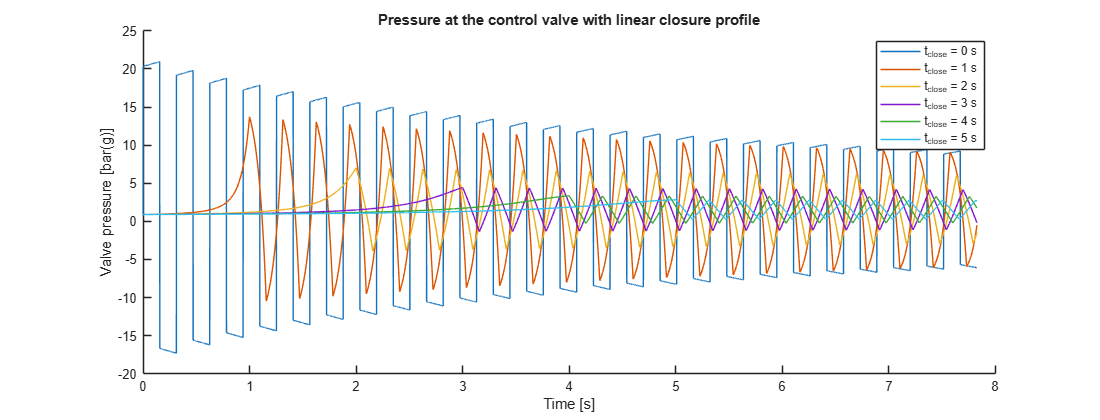

%% Valve pressure history for each closing time
figure('Position',[140 140 1100 420]); hold on;

for i = 1:numel(results)
    plot(results{i}.t, results{i}.pressureGauge(end,:)/1e5);
end

xlabel('Time [s]'); ylabel('Valve pressure [bar(g)]');

legendStrings = arrayfun(@(t) sprintf('t_{close} = %g s', t), closureTimes, 'UniformOutput', false);
legend(legendStrings);

title('Pressure at the control valve with linear closure profile');
% Save the current figure (pressure vs time) to a JPEG file
saveas(gcf,'valve_pressure_history.jpg');

The valve location is not necessarily where the worst pressure occurs. Spatial envelopes therefore check the maximum and minimum pressure reached at every point along the pipe over the full transient.

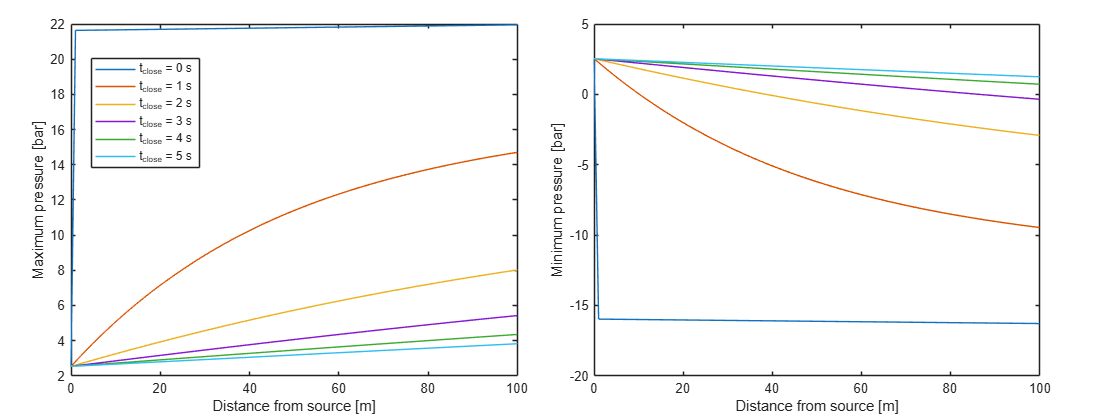

%% Pressure envelopes along the pipeline
figure('Color','w','Position',[140 140 1100 420]); grid on
tiledlayout(1,2,'Padding','compact','TileSpacing','compact');

nexttile
for k = 1:numel(results)
    plot(results{k}.x,max(results{k}.pressureBarA,[],2)); hold on
end
legendStrings = arrayfun(@(t) sprintf('t_{close} = %g s', t), closureTimes, 'UniformOutput', false);
legend(legendStrings, 'Location','best');
xlabel('Distance from source [m]'); ylabel('Maximum pressure [bar]'); 

nexttile
for k = 1:numel(results)
    plot(results{k}.x,min(results{k}.pressureBarA,[],2)); hold on
end
xlabel('Distance from source [m]'); ylabel('Minimum pressure [bar]');

Closures of 0–3 s cause the single-phase MOC solution to cross the water vapour-pressure threshold. The calculated sub-vapour pressures are not physical pressure predictions; they indicate that column separation may occur and that a cavitation-capable model would be required. The 4 s and 5 s cases retain positive vapour-pressure margins.

%% Vapor-pressure margin check
vaporPressureBar = fluid.vaporPressure/1e5;   % bar, absolute
vaporMarginBar = minBar - vaporPressureBar;   % bar, positive = safe margin above vapor pressure

vaporMarginTable = table(closureTimes(:), minBar, vaporMarginBar, ...
        'VariableNames', {'ClosureTime [s]','MinPressure [bar abs]','VaporMargin [bar]'})

vaporMarginTable = 6×3 table
    ClosureTime [s]    MinPressure [bar abs]    VaporMargin [bar]
    _______________    _____________________    _________________
           0                  -16.286                -16.318     
           1                  -9.4627                -9.4944     
           2                   -2.897                -2.9287     
           3                 -0.34677               -0.37847     
           4                  0.72792                0.69622     
           5                   1.2525                 1.2208     
	Get insights using Copilot